# Error with respect to lambda and distortion magnitude

## Load and initiate

lambda = [0.1 0.2 0.3];

minllist = [1 2 5 10 15];
maglist = [0.1:0.1:0.9 1:0.25:2];

load Lambda_vs_noise.mat

confidence_level = 0.9999999;
zscore = zscorer(confidence_level);

## Plot

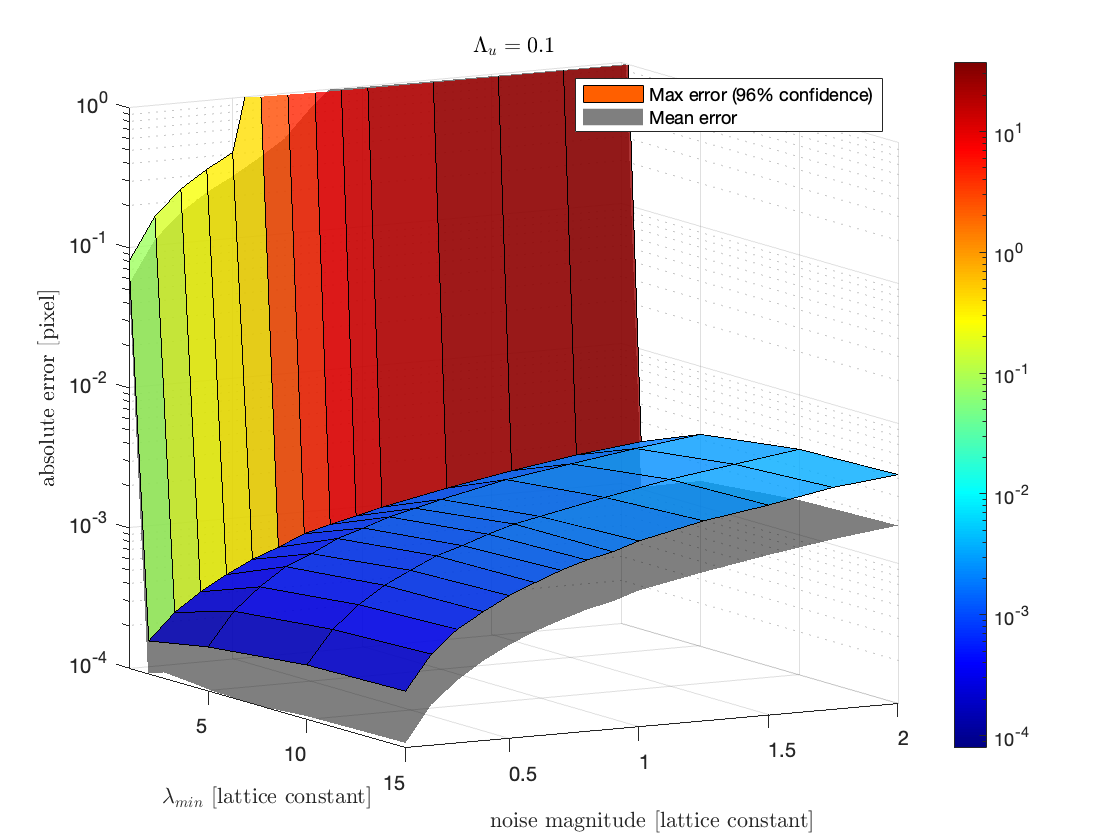

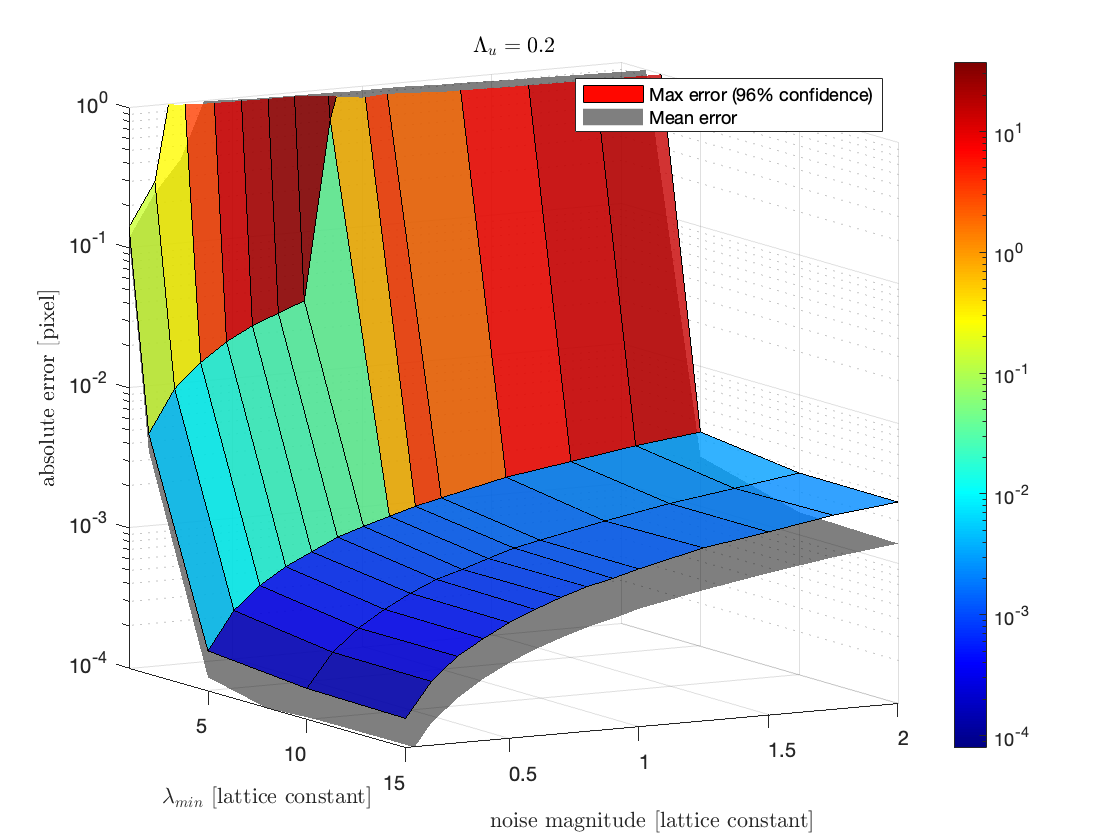

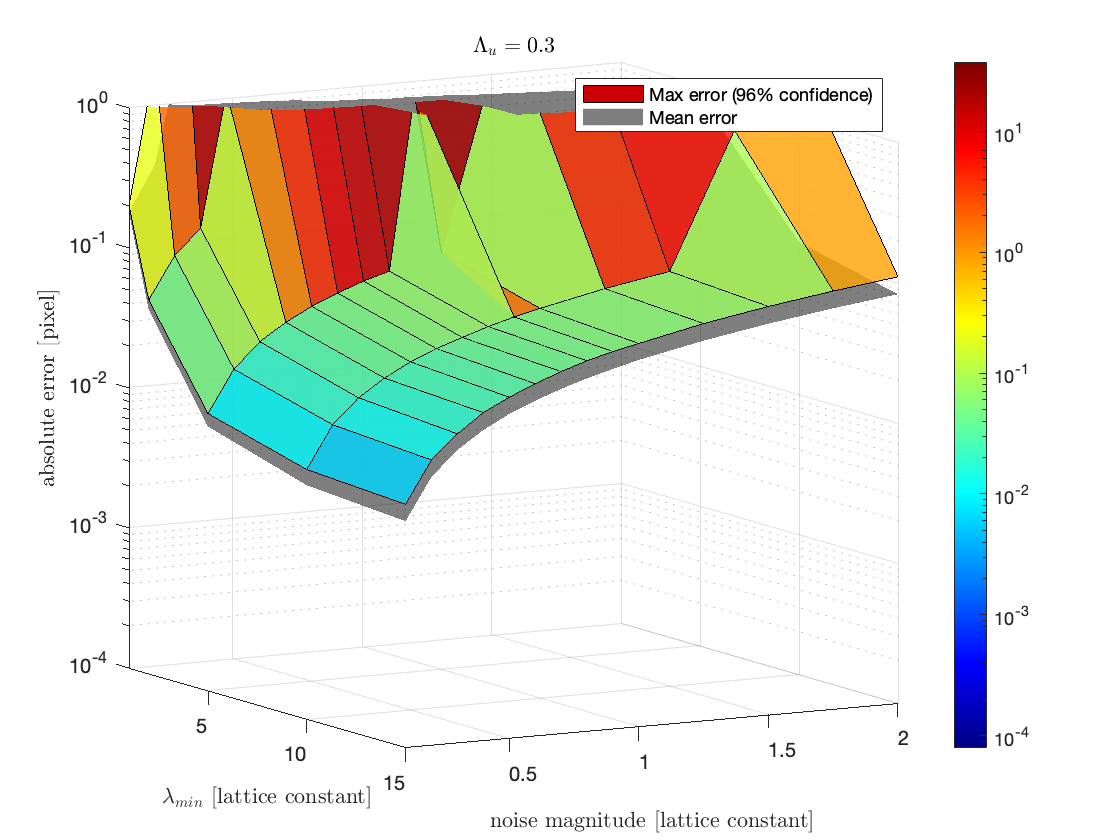

for ctr = 1:3
    [x, y] = meshgrid(minllist,maglist);
    figure;
    surf(x,y,zscore*stds(:,:,ctr)+means(:,:,ctr),'FaceAlpha',0.8);
    colormap(jet);
    xlabel("$\lambda_{min}$ [lattice constant]","Interpreter","latex");
    ylabel("noise magnitude [lattice constant]","Interpreter","latex");
    zlabel("absolute error [pixel]","Interpreter","latex");
    axis tight
    set(gca,'zscale','log');
    set(gca, "ColorScale","log");
    zlim([0.0001 1])
    hold on
    surf(x,y,means(:,:,ctr),'edgecolor','none','FaceColor','k','FaceAlpha',0.5);
%     surf(x,y,-zscore*stds(:,:,ctr)+means(:,:,ctr),'edgecolor','none','FaceColor','k','FaceAlpha',0.25);
    colorbar;
    clim([min(means(:)) max(means(:))]);
%     clim([0.001 1])
    legend('Max error (96% confidence)','Mean error','Location','northeast');
    title("$\Lambda_u = " + lambda(ctr) + "$","Interpreter","latex");
    view([60.682 9.302])
    hold off
%     saveas(gcf,"lambda " + lambda(ctr) + " vs noise.fig");
end